# Polynomial interpolation

Nel seguito di questo notebook verrà presentato un approccio alla base del ML: fitting polinomiale. Nello specifico verranno generati dei punti casualmente distribuiti attorno alla funzione seno e si otterà il polinomio interpolante (overfitting) che attraversa tutti i punti (di learning). In seguito si rappresenteranno polinomi aventi gradi inferiori a $n-1$ (dove $n$ rappresenta il numero di punti precedentemente generati) e si calcolerà lo scarto quadratico medio o root mean square error $E_{RMS}$ per ogni grado.

% cleaning enviroment
clc
clear

Rappresento la funzione $y = sin(2\pi x)$ con $0 \leq x\leq 1$

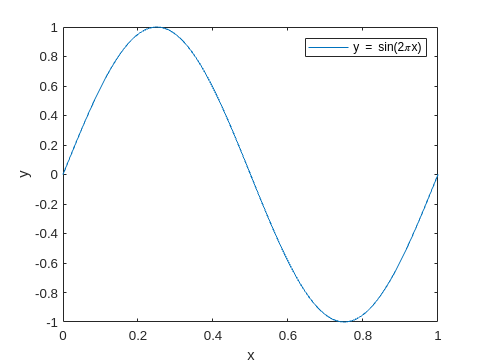

% funzione seno
sen = @(x) sin(2*pi*x);

% genero vettori
x = linspace(0,1,100);
y = sen(x);

% plotto funzione seno
figure;
plot(x,y)
xlabel("x")
ylabel("y")
legend("y = sin(2\pix)")

Genero set di learning avente `n_lrn` punti randomicamente distribuiti attorno alla funzione seno

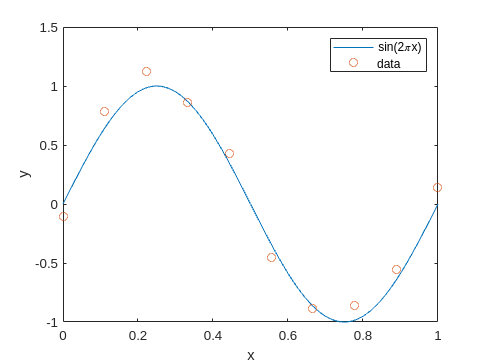

% genero set di learning
n_lrn = 10;
x_lrn = linspace(0,1,n_lrn);
eps = 0.15;
y_lrn = sin(2*pi*x_lrn);
y_lrn = y_lrn + (-eps + (2.*eps).*rand(n_lrn,1))';

figure
plot(x,y)
hold on
plot(x_lrn,y_lrn,"o")
legend("sin(2\pix)","data")
xlabel("x")
ylabel("y")
hold off

Il **polinomio interpolante** è quel polinomio la cui curva passa attraverso tutti i punti sperimentali. Se il polinomio ha forma generale $y=a_1 + a_2 x + a_3 x^3 + ... + a_n x^{n-1}$ dove 

- $n$ è il numero di punti da fittare;

- $a_1$, $a_2$, ..., $a_n$ sono gli $n$ coefficienti del polinomio;

Posto $\bar{x} = (x_1, x_2, ..., x_n)$, affinchè il polinomio attraversi tutti i punti del vettore $\bar{x}$ deve verificare le seguenti condizioni:

- $y_1=a_1 + a_2 x_1 + a_3 x_1^3 + ... + a_n x_1^{n-1}$     (condizione passaggio per il punto $x_1$)

- $y_2=a_1 + a_2 x_2 + a_3 x_2^3 + ... + a_n x_2^{n-1}$     (condizione passaggio per il punto $x_2$)

- ...

- $y_n=a_1 + a_2 x_n + a_3 x_n^3 + ... + a_n x_n^{n-1}$     (condizione passaggio per il punto $x_n$)

che rappresenta un sistema di $n$ equazioni in $n$ incognite. Il nostro obiettivo consiste nel risolvere il sistema per determinare gli $n$ coefficienti $a_1$, $a_2$, ..., $a_n$ e quindi il polinomio interpolante.

Sfruttando il formalismo matriciale è possibile rappresentare il sistema di $n$ equazioni come di seguito


$$\pmatrix{y_1 \cr y_2 \cr ... \cr y_n} = \pmatrix{1 & x_1 & x_1^2 & ... & x_1^{n-1} \cr 1 & x_2 & x_2^2 & ... & x_2^{n-1} \cr ... & ... & ... & ... & ... \cr 1 & x_n & x_n^2 & ... & x_n^{n-1}} \cdot \pmatrix{a_1 \cr a_2 \cr ... \cr a_n}$$


La matrice $\pmatrix{1 & x_1 & x_1^2 & ... & x_1^{n-1} \cr 1 & x_2 & x_2^2 & ... & x_2^{n-1} \cr ... & ... & ... & ... & ... \cr 1 & x_n & x_n^2 & ... & x_n^{n-1}}$ prende il nome "matrice di Vandermonde" e si genera a partire da un singolo vettore <

% genero matrice di Vandermonde
V = fliplr(vander(x_lrn))

Risolvo il sistema $y = \alpha V$ dove $\alpha$ sono i coefficienti del polinomio cercato: $y = \alpha_1 + \alpha_2 x_1 + \alpha_3 x_2^2+...$

Alla luce della forma matriciale, è possibile determinare i coefficienti $\alpha$ eseguendo il prodotto righe per colonna tra l'inversa della matrice di Vandermonde e il vettore colonna y

% determino i coefficienti
% a = pinv(V)*(y_lrn')
a = V\y_lrn'

V =     1.0000         0         0         0         0         0         0         0         0         0
    1.0000    0.1111    0.0123    0.0014    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2222    0.0494    0.0110    0.0024    0.0005    0.0001    0.0000    0.0000    0.0000
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001
    1.0000    0.4444    0.1975    0.0878    0.0390    0.0173    0.0077    0.0034    0.0015    0.0007
    1.0000    0.5556    0.3086    0.1715    0.0953    0.0529    0.0294    0.0163    0.0091    0.0050
    1.0000    0.6667    0.4444    0.2963    0.1975    0.1317    0.0878    0.0585    0.0390    0.0260
    1.0000    0.7778    0.6049    0.4705    0.3660    0.2846    0.2214    0.1722    0.1339    0.1042
    1.0000    0.8889    0.7901    0.7023    0.6243    0.5549    0.4933    0.4385    0.3897    0.3464
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0


% ottengo il polinomio funzione degli scalari x e m (grado)
poly = @(x,m) (x.^(0:m))*(a(1:m+1));

% over-fitting

a = 1.0e+05 *

   -0.0000
   -0.0004
    0.0125
   -0.1140
    0.5291
   -1.4203
    2.2869
   -2.1773
    1.1295
   -0.2460


z = zeros(1,100);
for i=1:100
    z(i) = poly(x(i),n_lrn-1);
end

figure;
plot(x,z,"r")
hold on
plot(x_lrn,y_lrn,'ob')
plot(x,y,"g")
hold off
legend("polynomial fit", "data", "sin(2\pix)")
xlabel("x")
ylabel("y")
ylim([-1.5 1.5])
xlim([0 1])

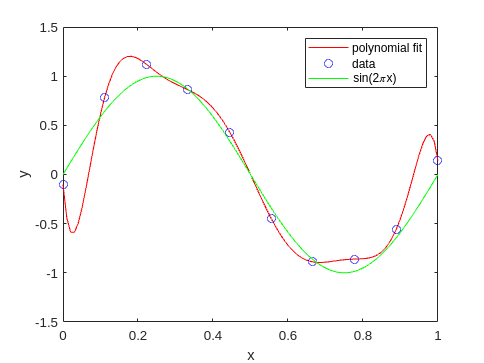

% plotting at different M (polynomial order)

% plot M = 0
figure;
plot(x,repelem(a(1),length(x)),"r")

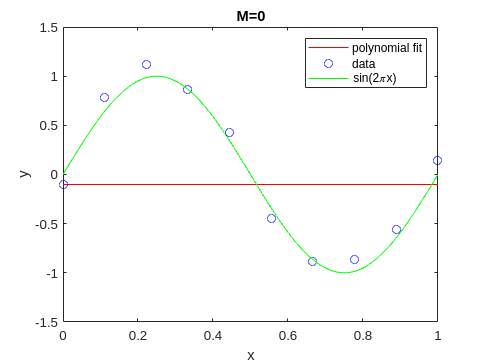

hold on
plot(x_lrn,y_lrn,'ob')
plot(x,y,"g")
hold off
legend("polynomial fit", "data", "sin(2\pix)")
xlabel("x")
ylabel("y")
ylim([-1.5 1.5])
xlim([0 1])
title("M=0")

% plot M = 1
figure;
plot(x,(a(1)+a(2).*x),"r")
hold on
plot(x_lrn,y_lrn,'ob')

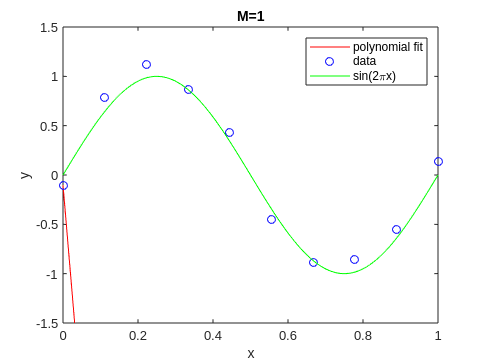

plot(x,y,"g")
hold off
legend("polynomial fit", "data", "sin(2\pix)")
xlabel("x")
ylabel("y")
ylim([-1.5 1.5])
xlim([0 1])
title("M=1")

% plot M = 3
figure;
plot(x,(a(1) + (a(2).*x) + a(3).*x.^2 + a(4).*x.^3),"r")
hold on
plot(x_lrn,y_lrn,'ob')

plot(x,y,"g")
hold off
legend("polynomial fit", "data", "sin(2\pix)")
xlabel("x")
ylabel("y")
ylim([-1.5 1.5])
xlim([0 1])
title("M=3")

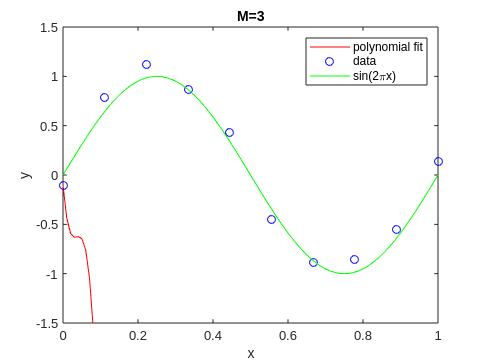

% learning error

% initializing vectors
learning_error = zeros(1,n_lrn);
y_fit = learning_error;


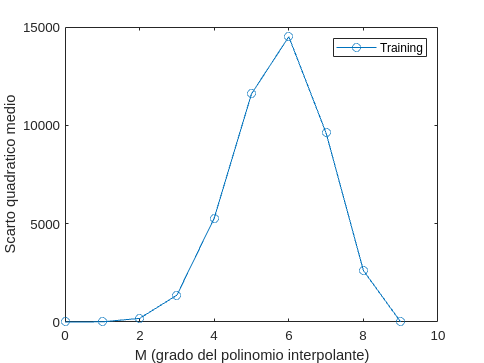

for j = 1:n_lrn

    % estimate y points
    for i = 1:n_lrn
        y_fit(i) = poly(x_lrn(i),j-1);
    end

    % calculating learning error
    learning_error(j) = sqrt(sum((y_fit-y_lrn).^2))/n_lrn;
end

% plotting learning error
plot(0:n_lrn-1,learning_error,"-o")
xlabel("M (grado del polinomio interpolante)")
ylabel("Scarto quadratico medio")
legend("Training")